GAUSSIAN PROCESS FROM LIBRARY CARL RASMUSSEN MIT

`  training: [nlZ dnlZ] = gp(hyp, inf, mean, cov, lik, x, y);` `nlZ` is the negative log marginal likelihood and `dnlZ` its partial derivatives wrt the hyperparameters (which are used for training the hyperparameters). 

` prediction: [ymu ys2 fmu fs2 lp] = gp(hyp, inf, mean, cov, lik, x, y, xs, ys); t`he prediction outputs are `ymu` and `ys2` for test output mean and covariance, and `fmu` and `fs2` are the equivalent quanteties for the corresponding latent variables. Finally, `lp` are the test output log probabilities

`Keep the 10% secret (X, Y), and only use this at the very end when we know what we are testing for (its a seecret) USE X/YT`

`Either use CV for tunning into different length scales per kernel + mean function? `

`or if different approach you can still do another 10% partition test`

% make sure to add to environment the gp_mit package with SUBfolders
data = readtable('data_reduced.csv')

data = 328×47 table
    Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    matrixSTRENGTH    matrixStrainbreak    matrixImpact    impurityE    impuritySTRENGTH    impurityStrainbreak    impurityImpact    matrixXc    impurityXc    blendE    blendSTRENGTH    blendStrainbreak    blendImpact    MajorityPolymer_H

lables= data.Properties.VariableNames

lables = 1×47 cell array
    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'matrixSTRENGTH'}    {'matrixStrainbreak'}    {'matrixImpact'}    {'impurityE'}    {'impuritySTRENGTH'}    {'impurityStrainbreak'}    {'impurityImpact'}    {'matrixXc'}    {'impurityXc'}    {'blendE'}    {'blendSTRENGTH'}    {'blendStrainbreak'}    {'blendImpact'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'Min

lables = cell2table(lables);
lablesS = lables(1, 1:13);
lablesS2 = lables(1,28:end);
lablesE= [lablesS, lables(1,14), lables(1,18), lables(1,22:23), lablesS2];
lablesYE= lables(1,24);

12 features + %impurity

col 14 matrix E, 18 impurity E

col 22, 23 Matrix/imp XC

col 24 blendE

col 28 start of 1H (Majority and min polymers)

afetr preprocessing  (in XE ) there are only 5 vars non-discrete, and one is the percentage of mixture so that is already scaled to range between 0-1, 

14-17  will then just be divided by thir respective maxs and adjust to the scale. 

% skipping  Strenth Impact Strain Break
E =  table2array(data(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

E = 1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020  


% normalize to range 0-1 
Xe= [E(:,1:17), E(:,19:end)];
Ye = E(:,18)./max (E(:,18)); 
cols_continuous_norm = Xe(:,14:17) ./ max(Xe(:,14:17)); 
Xe(:,14:17)= cols_continuous_norm;
% what about encoded vars?!!
% means = mean(Xe); Xe = Xe - means 

## keep 10% and stratify yE in 5 bins 

THIS test  set is not used until the very end to asses how they all do equally, SECRET

*repeatng : `Keep the 10% secret (X, Y), and only use this at the very end when we know what we are testing for (its a seecret) USE X/YT`

`Either use CV for tunning into different length scales per kernel + mean function? `

`or if different approach you can still do another 10% partition test`

%creating 5 bins 
binEdgesI = linspace(min(Ye), max(Ye), 6)

binEdgesI =     0.0302    0.2242    0.4181    0.6121    0.8060    1.0000


% Get the bin indices for each instance
binIndicesI = discretize(Ye, binEdgesI)

binIndicesI =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% Split the data into a training set and test set with stratification
cvI = cvpartition(binIndicesI, 'Holdout', 0.1)

cvI = Hold-out cross validation partition
   NumObservations: 328
       NumTestSets: 1
         TrainSize: 296
          TestSize: 32

%boolean vectors
trainingIndicesI = training(cvI);
secretIndices = test(cvI);

XT = Xe(trainingIndicesI,:);
Xsecret = Xe(secretIndices, :);
YT = Ye(trainingIndicesI);
Ysecret = Ye(secretIndices);

### HOLDOUT method validation 10% set (10%secretTEst,

% fast splitting for training and validation set 
 [r, c ]=size(XT)

r = 296

c = 29

 PD = 0.90 ;
 idx = randperm(r);
 Xtrain = XT(idx(1:round(r*PD)),:);
 XVal = XT(idx(round(r*PD)+1:end),:);

Ytrain = YT(idx(1:round(r*PD)),:);
YVal = YT(idx(round(r*PD)+1:end),:);

### CV : (val +train)90% for 10-k fold  (10%secret,

redo binIndices with the training set, as binIndices

binEdgesT = linspace(min(YT), max(YT), 6)

binEdgesT =     0.0302    0.2242    0.4181    0.6121    0.8060    1.0000


binIndicesT = discretize(YT, binEdgesT)

binIndicesT =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


cv        = cvpartition(binIndicesT,'kfold',10);
numtestsets   = cv.NumTestSets;

#### Trying simple regression 1D 

practice so holdout method

%Trying simple regression 1D 
x = Xtrain(:,14);
xs = XVal(:,14)

xs =     0.0537
    0.2711
    0.7057
    0.0601
    0.5531
    0.0374
    0.7057
    0.0537
    0.5448
    0.0304


y = Ytrain;
ys = YVal;

%HYPermeter : [mean, cov, lik] and GP(hyp, inference, name_functions m, c,
%l, x, y, and if test ) HYP should agree with specific NAME

meanfunc = [];    covfunc = @covSEiso;   likfunc = @likGauss; 
hyp = struct('mean', [] , 'cov', [0 0], 'lik', log(0.1));
nlml = gp(hyp, @infGaussLik, meanfunc , covfunc, likfunc, x, y)

nlml = -183.1060


%  gp returns the mean m variance s2 at the test location (each)
%s2 to shown the confidence interval bound 
[m, s2] = gp(hyp,@infGaussLik, meanfunc, covfunc, likfunc, x, y, xs)

m =     0.1034
    0.2874
    0.6482
    0.1086
    0.5278
    0.0901
    0.6482
    0.1034
    0.5210
    0.0845


s2 =     0.0101
    0.0101
    0.0101
    0.0101
    0.0101
    0.0102
    0.0101
    0.0101
    0.0101
    0.0102



 n = size(m,1); mape_training =  calculateMAPE(ys,m)

mape_training = 25.0523


hyp1 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value -1.831060e+02
Function evaluation      5;  Value -1.885735e+02
Function evaluation      8;  Value -1.898842e+02
Function evaluation     12;  Value -1.898845e+02
Function evaluation     17;  Value -1.899044e+02
Function evaluation     20;  Value -1.899049e+02
Function evaluation     23;  Value -1.899066e+02
Function evaluation     26;  Value -1.899066e+02
Function evaluation     28;  Value -1.899066e+02
Function evaluation     30;  Value -1.899066e+02
Function evaluation     33;  Value -1.899066e+02
Function evaluation     35;  Value -1.899066e+02
Function evaluation     39;  Value -1.899066e+02
Function evaluation     41;  Value -1.899066e+02
Function evaluation     44;  Value -1.899066e+02
Function evaluation     47;  Value -1.899066e+02
Function evaluation     50;  Value -1.899066e+02
Function evaluation     53;  Value -1.899066e+02
Function evaluation     56;  Value -1.899066e+02
Function evaluation     58;  Value -1.899066e+02
Function evaluation 

infered_noise_st= exp(hyp1.lik)

infered_noise_st = 0.1145

nlml1 = gp(hyp1, @infGaussLik, meanfunc, covfunc, likfunc, x, y)

nlml1 = -189.9066

 %exp(nlml2 -nlml) = ratio decrease of joint probality (density) of training
%data
dec_jp = exp(nlml1 -nlml) 

dec_jp = 0.0011

%mape_values_1D= zeros(10,1)
 %for i=1 : 10
   hyp2 = minimize(hyp1, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value -1.899066e+02


   [ymu1D, ys21D,fmu1D, fs21D, lp1D] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs, ys)

ymu1D =     0.1038
    0.2905
    0.6449
    0.1093
    0.5263
    0.0899
    0.6449
    0.1038
    0.5196
    0.0840


ys21D =     0.0133
    0.0132
    0.0132
    0.0133
    0.0132
    0.0133
    0.0132
    0.0133
    0.0132
    0.0133


fmu1D =     0.1038
    0.2905
    0.6449
    0.1093
    0.5263
    0.0899
    0.6449
    0.1038
    0.5196
    0.0840


fs21D = 1.0e-03 *

    0.1610
    0.0905
    0.0951
    0.1545
    0.1016
    0.1797
    0.0951
    0.1610
    0.1020
    0.1886


lp1D =     1.2282
    1.2245
    1.2266
    1.1191
    1.2240
    1.2270
    1.1260
   -0.0269
    1.1608
    1.1933


     n = size(ymu1D, 1); mape_1D = calculateMAPE(ys,ymu1D )

mape_1D = 25.0272

 %end
%mape_1D = mean(mape_values_1D)


%confidence interval of predictions
ci =[ymu1D+2*sqrt(ys21D), ymu1D-2*sqrt(ys21D)]; corr1D = corr(ymu1D, ys )

corr1D = 0.9657

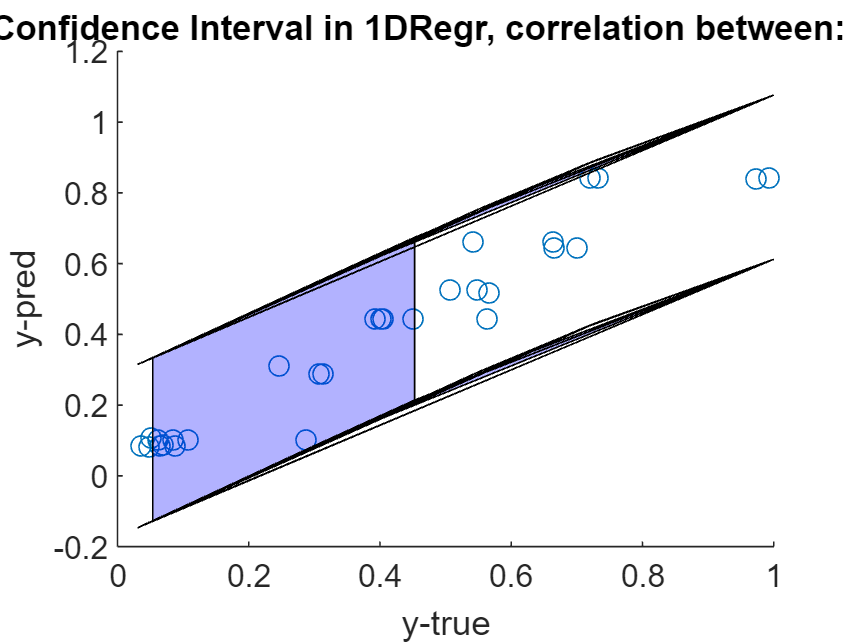

figure;
scatter(ys, ymu1D)
hold on;
patch([xs; flip(xs)], [ci(:,1); flip(ci(:,2))], 'b', 'FaceAlpha', 0.3);
xlabel('y-true');
ylabel('y-pred');
title(['95% Confidence Interval in 1DRegr, correlation between: ' num2str(corr1D)] );
hold off;

hyp = struct with fields:
    mean: []
     cov: [2×1 double]
     lik: -2.3026


Function evaluation      0;  Value -1.831741e+02
Function evaluation      5;  Value -1.886054e+02
Function evaluation      9;  Value -1.905893e+02
Function evaluation     12;  Value -1.911645e+02
Function evaluation     14;  Value -1.921325e+02
Function evaluation     16;  Value -1.923829e+02
Function evaluation     18;  Value -1.925946e+02
Function evaluation     20;  Value -1.926147e+02
Function evaluation     25;  Value -1.932332e+02
Function evaluation     28;  Value -1.932608e+02
Function evaluation     32;  Value -1.936378e+02
Function evaluation     36;  Value -1.944187e+02
Function evaluation     40;  Value -1.946941e+02
Function evaluation     43;  Value -1.956650e+02
Function evaluation     45;  Value -1.959834e+02
Function evaluation     47;  Value -1.960640e+02
Function evaluation     50;  Value -1.960689e+02
Function evaluation     54;  Value -1.961608e+02
Function evaluation     57;  Value -1.965438e+02
Function evaluation     59;  Value -1.972642e+02
Function evaluation 

mape1D_means = 29.0100

 %NN does not work!
 %meanfunc= @meanNN ; 
% meanfunc = []; hyp.mean =[];
% cannot make mean discrete to work either.. 
% meanfunc= @meanDiscrete; hyp.mean = mean(x);
% hypD = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);
% [ymuD, ys2D,fmu, fs2, lp] = gp(hypD, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs, ys);
% n = size(ymu, 1) ; mape1D_meanD =  calculateMAPE(ys, ymuD,  n)
 %"   hyp = [
%         mu_2
%         ..
%         mu_s ]
covfunc = @covSEiso; hyp.cov= [0; 0]
likfunc = @likGauss; sn = 0.1; hyp.lik = log(sn);

meanfunc = {@meanSum, {@meanLinear, @meanConst}}; hyp.mean = [0.5; 1];

hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

[ymu, ys2,fmu, fs2, lp] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs, ys);
n = size(ymu, 1) ; mape1D_means =  calculateMAPE(ys, ymu)

By changing the mean function to a sum of linear and constant, almost no improvement was clear 

### 2D prediction, still basic config

% starting with a 2d gp 
Xt2 = XT(:,13:14)

Xt2 =     0.5000    0.0601
    0.2000    0.0601
    0.1000    0.0601
    0.0500    0.0601
    0.0250    0.0601
    0.0100    0.0601
         0    0.0601
    0.2000    0.0601
    0.1000    0.0601
    0.0500    0.0601


meanfunc = [];                    % empty: don't use a mean function
covfunc = @covSEiso;              % Squared Exponental covariance function
likfunc = @likGauss;  
hyp2D = struct('mean', [], 'cov', [0 0], 'lik', -1);


%use CV to have ten times in different subsets 
mape_values= zeros(10,1)

mape_values =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for k = 1 : 10 
    xtrain = Xt2(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = Xt2(cv.test(k),:); ytest = YT(cv.test(k),:);
    size(xtrain,1)
    hyp2D = minimize(hyp2D, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp2D, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);
    mape_values(k) = calculateMAPE(ytest, ymu)
end 

ans = 267

Function evaluation      0;  Value -2.791062e+00
Function evaluation     10;  Value -2.604168e+02
Function evaluation     13;  Value -2.614165e+02
Function evaluation     17;  Value -2.614207e+02
Function evaluation     18;  Value -2.614242e+02
Function evaluation     21;  Value -2.614243e+02
Function evaluation     25;  Value -2.614243e+02
Function evaluation     27;  Value -2.614243e+02
Function evaluation     31;  Value -2.614246e+02
Function evaluation     34;  Value -2.614246e+02
Function evaluation     36;  Value -2.614246e+02
Function evaluation     39;  Value -2.614246e+02
Function evaluation     42;  Value -2.614246e+02
Function evaluation     44;  Value -2.614246e+02
Function evaluation     46;  Value -2.614246e+02
Function evaluation     48;  Value -2.614246e+02
Function evaluation     51;  Value -2.614246e+02
Function evaluation     57;  Value -2.614246e+02
Function evaluation     59;  Value -2.614246e+02
Function evaluation     64;  Value -2.614246e+02
Function evaluation 

mape_values =    17.3292
         0
         0
         0
         0
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.639940e+02
Function evaluation      3;  Value -2.640618e+02
Function evaluation      4;  Value -2.640896e+02
Function evaluation      7;  Value -2.640900e+02
Function evaluation     12;  Value -2.641099e+02
Function evaluation     16;  Value -2.641100e+02
Function evaluation     18;  Value -2.641101e+02
Function evaluation     21;  Value -2.641101e+02
Function evaluation     25;  Value -2.641101e+02
Function evaluation     27;  Value -2.641101e+02
Function evaluation     29;  Value -2.641101e+02
Function evaluation     31;  Value -2.641101e+02
Function evaluation     33;  Value -2.641101e+02
Function evaluation     35;  Value -2.641101e+02
Function evaluation     41;  Value -2.641101e+02
Function evaluation     44;  Value -2.641101e+02
Function evaluation     46;  Value -2.641101e+02
Function evaluation     49;  Value -2.641101e+02
Function evaluation     51;  Value -2.641101e+02
Function evaluation     54;  Value -2.641101e+02


mape_values =    17.3292
   24.2767
         0
         0
         0
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.575868e+02
Function evaluation      3;  Value -2.577337e+02
Function evaluation      5;  Value -2.577479e+02
Function evaluation      8;  Value -2.577481e+02
Function evaluation     12;  Value -2.577481e+02
Function evaluation     15;  Value -2.577481e+02
Function evaluation     17;  Value -2.577481e+02
Function evaluation     41;  Value -2.577481e+02


mape_values =    17.3292
   24.2767
   21.9259
         0
         0
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.663639e+02
Function evaluation      3;  Value -2.666429e+02
Function evaluation      4;  Value -2.666620e+02
Function evaluation      5;  Value -2.666635e+02
Function evaluation      7;  Value -2.666638e+02
Function evaluation      9;  Value -2.666646e+02
Function evaluation     12;  Value -2.666646e+02
Function evaluation     14;  Value -2.666646e+02
Function evaluation     16;  Value -2.666646e+02
Function evaluation     18;  Value -2.666647e+02
Function evaluation     20;  Value -2.666647e+02
Function evaluation     23;  Value -2.666647e+02
Function evaluation     25;  Value -2.666647e+02
Function evaluation     27;  Value -2.666647e+02
Function evaluation     31;  Value -2.666647e+02
Function evaluation     33;  Value -2.666647e+02
Function evaluation     35;  Value -2.666647e+02
Function evaluation     38;  Value -2.666647e+02
Function evaluation     41;  Value -2.666647e+02
Function evaluation     43;  Value -2.666647e+02
Function evaluation 

mape_values =    17.3292
   24.2767
   21.9259
   38.5291
         0
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.555873e+02
Function evaluation      3;  Value -2.560095e+02
Function evaluation      4;  Value -2.560522e+02
Function evaluation      6;  Value -2.560567e+02
Function evaluation      8;  Value -2.560674e+02
Function evaluation     11;  Value -2.560675e+02
Function evaluation     13;  Value -2.560676e+02
Function evaluation     15;  Value -2.560676e+02
Function evaluation     17;  Value -2.560676e+02
Function evaluation     19;  Value -2.560676e+02
Function evaluation     21;  Value -2.560676e+02
Function evaluation     22;  Value -2.560676e+02
Function evaluation     25;  Value -2.560676e+02
Function evaluation     26;  Value -2.560676e+02
Function evaluation     28;  Value -2.560676e+02
Function evaluation     30;  Value -2.560676e+02
Function evaluation     32;  Value -2.560676e+02
Function evaluation     34;  Value -2.560676e+02
Function evaluation     35;  Value -2.560676e+02
Function evaluation     37;  Value -2.560676e+02
Function evaluation 

mape_values =    17.3292
   24.2767
   21.9259
   38.5291
   12.9369
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.547008e+02
Function evaluation      4;  Value -2.547236e+02
Function evaluation      6;  Value -2.547644e+02
Function evaluation      9;  Value -2.547647e+02
Function evaluation     13;  Value -2.547686e+02
Function evaluation     15;  Value -2.547718e+02
Function evaluation     18;  Value -2.547720e+02
Function evaluation     20;  Value -2.547720e+02
Function evaluation     23;  Value -2.547720e+02
Function evaluation     27;  Value -2.547720e+02
Function evaluation     29;  Value -2.547720e+02
Function evaluation     30;  Value -2.547720e+02
Function evaluation     33;  Value -2.547720e+02
Function evaluation     37;  Value -2.547720e+02
Function evaluation     39;  Value -2.547720e+02
Function evaluation     42;  Value -2.547720e+02
Function evaluation     52;  Value -2.547720e+02
Function evaluation     54;  Value -2.547720e+02
Function evaluation     59;  Value -2.547720e+02
Function evaluation     62;  Value -2.547720e+02
Function evaluation 

mape_values =    17.3292
   24.2767
   21.9259
   38.5291
   12.9369
   12.3284
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.538794e+02
Function evaluation      4;  Value -2.538948e+02
Function evaluation      5;  Value -2.539096e+02
Function evaluation      8;  Value -2.539096e+02
Function evaluation     11;  Value -2.539096e+02
Function evaluation     13;  Value -2.539098e+02
Function evaluation     16;  Value -2.539107e+02
Function evaluation     18;  Value -2.539112e+02
Function evaluation     20;  Value -2.539114e+02
Function evaluation     23;  Value -2.539114e+02
Function evaluation     25;  Value -2.539114e+02
Function evaluation     27;  Value -2.539114e+02
Function evaluation     31;  Value -2.539114e+02
Function evaluation     33;  Value -2.539114e+02
Function evaluation     35;  Value -2.539114e+02
Function evaluation     37;  Value -2.539114e+02
Function evaluation     38;  Value -2.539114e+02
Function evaluation     40;  Value -2.539114e+02
Function evaluation     42;  Value -2.539114e+02
Function evaluation     44;  Value -2.539114e+02
Function evaluation 

mape_values =    17.3292
   24.2767
   21.9259
   38.5291
   12.9369
   12.3284
   13.6476
         0
         0
         0


ans = 267

Function evaluation      0;  Value -2.562931e+02
Function evaluation      4;  Value -2.562995e+02
Function evaluation      6;  Value -2.563090e+02
Function evaluation      8;  Value -2.563098e+02
Function evaluation     12;  Value -2.563183e+02
Function evaluation     14;  Value -2.563204e+02
Function evaluation     16;  Value -2.563211e+02
Function evaluation     18;  Value -2.563211e+02
Function evaluation     20;  Value -2.563211e+02
Function evaluation     22;  Value -2.563212e+02
Function evaluation     24;  Value -2.563212e+02
Function evaluation     27;  Value -2.563212e+02
Function evaluation     29;  Value -2.563212e+02
Function evaluation     31;  Value -2.563212e+02
Function evaluation     34;  Value -2.563212e+02
Function evaluation     36;  Value -2.563212e+02
Function evaluation     38;  Value -2.563212e+02
Function evaluation     41;  Value -2.563212e+02
Function evaluation     43;  Value -2.563212e+02
Function evaluation     45;  Value -2.563212e+02
Function evaluation 

mape_values =    17.3292
   24.2767
   21.9259
   38.5291
   12.9369
   12.3284
   13.6476
   14.5246
         0
         0


ans = 267

Function evaluation      0;  Value -2.700291e+02
Function evaluation      3;  Value -2.708021e+02
Function evaluation      4;  Value -2.708207e+02
Function evaluation      6;  Value -2.708525e+02
Function evaluation      8;  Value -2.708623e+02
Function evaluation     10;  Value -2.708625e+02
Function evaluation     13;  Value -2.708625e+02
Function evaluation     15;  Value -2.708625e+02
Function evaluation     18;  Value -2.708625e+02
Function evaluation     22;  Value -2.708625e+02
Function evaluation     24;  Value -2.708625e+02
Function evaluation     26;  Value -2.708625e+02
Function evaluation     28;  Value -2.708625e+02
Function evaluation     30;  Value -2.708625e+02
Function evaluation     33;  Value -2.708625e+02
Function evaluation     35;  Value -2.708625e+02
Function evaluation     38;  Value -2.708625e+02
Function evaluation     41;  Value -2.708625e+02
Function evaluation     43;  Value -2.708625e+02
Function evaluation     46;  Value -2.708625e+02
Function evaluation 

mape_values =    17.3292
   24.2767
   21.9259
   38.5291
   12.9369
   12.3284
   13.6476
   14.5246
   19.1898
         0


ans = 267

Function evaluation      0;  Value -2.563723e+02
Function evaluation      3;  Value -2.570916e+02
Function evaluation      4;  Value -2.571520e+02
Function evaluation      6;  Value -2.571697e+02
Function evaluation      8;  Value -2.571840e+02
Function evaluation     10;  Value -2.571843e+02
Function evaluation     13;  Value -2.571843e+02
Function evaluation     14;  Value -2.571843e+02
Function evaluation     16;  Value -2.571843e+02
Function evaluation     20;  Value -2.571843e+02
Function evaluation     22;  Value -2.571843e+02
Function evaluation     24;  Value -2.571843e+02
Function evaluation     26;  Value -2.571843e+02
Function evaluation     28;  Value -2.571843e+02
Function evaluation     30;  Value -2.571843e+02
Function evaluation     32;  Value -2.571843e+02
Function evaluation     34;  Value -2.571843e+02
Function evaluation     36;  Value -2.571843e+02
Function evaluation     41;  Value -2.571843e+02
Function evaluation     48;  Value -2.571843e+02


mape_values =    17.3292
   24.2767
   21.9259
   38.5291
   12.9369
   12.3284
   13.6476
   14.5246
   19.1898
   14.6568


mape_2D = mean(mape_values)

mape_2D = 18.9345

mean_var = mean(ys2)

mean_var = 0.0077


[ymu2D ,ys2 ,fmu, fs2, lp] = gp(hyp2D, @infGaussLik, meanfunc, covfunc, likfunc, XT, YT, XVal, YVal);
mape = calculateMAPE(YVal, ymu2D)

mape = 3.3410

cov = hyp2D.cov;
ls = exp(cov(1))

ls = 1.0890

ns = exp(cov(2))

ns = 0.8144


kernel = @(x, y) ns^2 * exp(-0.5 * (x-y).^2 / ls^2);
% create a grid of points to evaluate the kernel function

% evaluate the kernel function at each point in the grid

K = kernel(XVal, YVal)

K =     0.6297    0.6297    0.6297    0.5551    0.5551    0.0000    0.5551    0.3074    0.6297    0.5551    0.5551    0.0002    0.5839    0.6623    0.6259    0.6467    0.6297    0.5551    0.5551    0.5551    0.6297    0.5551    0.5551    0.5551    0.5551    0.5551    0.5551    0.5551    0.5551
    0.6278    0.6278    0.6278    0.5583    0.5583    0.0000    0.5583    0.3038    0.6278    0.5583    0.5583    0.0002    0.5729    0.6609    0.6264    0.6477    0.6346    0.5583    0.5583    0.5583    0.5583    0.5583    0.5583    0.5583    0.5583    0.5583    0.5583    0.5583    0.5583
    0.6058    0.2452    0.5875    0.6058    0.6058    0.0001    0.6058    0.2452    0.5875    0.6058    0.6058    0.0001    0.6171    0.6632    0.6528    0.6169    0.6011    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058
    0.6393    0.1947    0.5379    0.6393    0.6393    0.0001    0.5379    0.5379    0.5379    0.6393    0.6393    0.0000   

K2 = kernel(XVal,ymu2D )

K2 =     0.6273    0.6273    0.6273    0.5590    0.5590    0.0000    0.5590    0.3030    0.6273    0.5590    0.5590    0.0002    0.5874    0.6619    0.6284    0.6484    0.6273    0.5590    0.5590    0.5590    0.6273    0.5590    0.5590    0.5590    0.5590    0.5590    0.5590    0.5590    0.5590
    0.6377    0.6377    0.6377    0.5411    0.5411    0.0000    0.5411    0.3234    0.6377    0.5411    0.5411    0.0003    0.5566    0.6629    0.6149    0.6397    0.6435    0.5411    0.5411    0.5411    0.5411    0.5411    0.5411    0.5411    0.5411    0.5411    0.5411    0.5411    0.5411
    0.6062    0.2445    0.5869    0.6062    0.6062    0.0001    0.6062    0.2445    0.5869    0.6062    0.6062    0.0001    0.6175    0.6632    0.6530    0.6165    0.6006    0.6062    0.6062    0.6062    0.6062    0.6062    0.6062    0.6062    0.6062    0.6062    0.6062    0.6062    0.6062
    0.6399    0.1936    0.5366    0.6399    0.6399    0.0001    0.5366    0.5366    0.5366    0.6399    0.6399    0.0000  

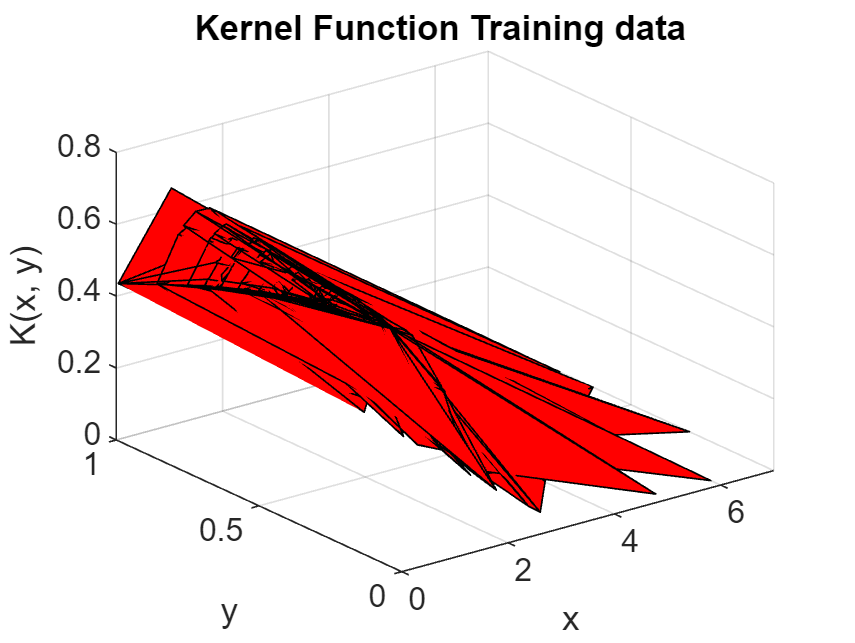


figure()
surf(XVal, YVal, K, 'FaceColor', 'r');
xlabel('x');
ylabel('y');
zlabel('K(x, y)');
title('Kernel Function Training data ');

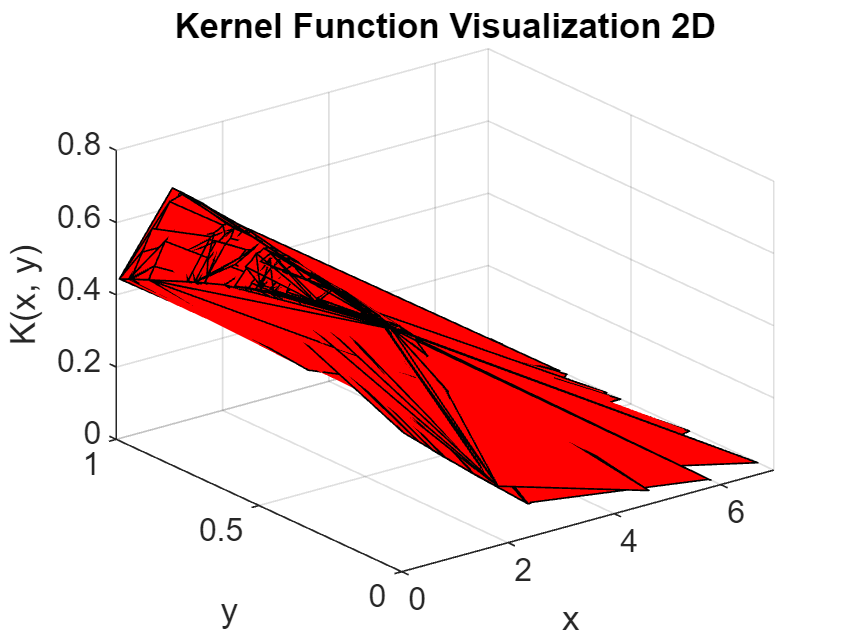


figure()
surf(XVal, ymu2D, K2, 'FaceColor', 'g');
xlabel('x');
ylabel('y');
zlabel('K(x, y)');
title('Kernel Function prediction');

#### materniso covariance

meanfunc = [];                    % empty: don't use a mean function
covfunc = {@covMaterniso, 3}; ell = 1.9174; sf = 0.611380; 
%covfunc = {@covDot,'iso'}; hypL.cov = log(0.4);
likfunc = @likGauss;  
hyp = struct('mean', [], 'cov', log([ell; sf]), 'lik', -1);


%use CV to have ten times in different subsets 
mape_values= zeros(10,1)
for k = 1 : 10 
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
    hyp2D = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp2D, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);
    mape_values(k) = calculateMAPE(ytest, ymu)
end 
mape_matern = mean(mape_values)
mean_var = mean(ys2)


#### doing CV with different kernels is complicated as they all have different param

meanfunc = [];                    % empty: don't use a mean function
cov_se = @covSEiso; hyp.cov = [0; 0];
cov_mat = {@covMaterniso, 3}; ell = 1/4; sf = 1; %hyp.cov = log([ell; sf]);
%infmet = @infLaplace;
likfunc = @likGauss;sn = 0.1; hyp.lik = log(sn);
% gaussian,laplce, 
% what we wanna test for ;  @likT has two paraam
kernels = {cov_se; cov_mat} %..., kernelN}; % list of kernels to compare
best_kernel = [];
best_nlZ = Inf;
likvalues = zeros(length(kernels), numtestsets);

% for i = 1:length(kernels)
%     for k= 1: numtestsets
%         %extract data first 
%         xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
%         xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
%         % train GP with kernel i
%         [nlZ, ~] = gp(hyp, inf, meanfunc,kernels(i) ,likfunc, xtrain, ytrain);
% 
%         % check if this model is better than the best one so far
%         if nlZ < best_nlZ
%             best_nlZ = nlZ;
%             best_kernel = kernels{i};
%         end
%         %calculate prediction 10 inner repetitions
%         latent_vars = zeros(10,2);
%         mape_avg =zeros(10,1);
%         for j= 1: 10
%             [ymu ,ys2 ,fmu, fs2 ,lp] = gp(hyp, inf, meanfunc,covfunc , kernels{i}, xtrain, ytrain, xtest, ytest);
%             n= size(ytest, 1); mape_avg(j,1) = calculateMAPE(ytest, ymu,n)
%             latent_vars(j,1) = fmu; latent_vars(j,2) = fs2;
%         end 
% 
%         likvalues(i,k) = mean(mape_avg);
%     end
% end

#### testing differnt likelihood function

% hyp.cov [lengthscale, signal st]
covfunc = @covSEiso; hyp.cov = [0; 0]; hyp.lik = [log(0.1), 2]; likfunc = @likT;
  [m ,s2] = gp(hyp, @infLaplace, [], covfunc, likfunc, x, y, xs);
  f = [m+2*sqrt(s2); flipdim(m-2*sqrt(s2),1)];
  fill([xs; flipdim(xs,1)], f, [7 7 7]/8)
  hold on; plot(xs, m); plot(x, y, '+')
  mape = calculateMAPE(ys, m)

%C = covSEiso(Xtrain)
meanfunc = [];                    % empty: don't use a mean function
covfunc = @covSEiso;              % Squared Exponental covariance function
likfunc = @likGauss;              % Gaussian likelihood

%2 log -param for SEiso
%always three param for theHYP STRUCT
hyp = struct('mean', [], 'cov', [0 0], 'lik', -1);

 %100 evaluations allowed 
hypE = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain);

Function evaluation      0;  Value 1.252524e+02
Function evaluation     14;  Value -2.584101e+02
Function evaluation     17;  Value -3.255189e+02
Function evaluation     20;  Value -3.291592e+02
Function evaluation     23;  Value -3.367665e+02
Function evaluation     25;  Value -3.411388e+02
Function evaluation     27;  Value -3.475491e+02
Function evaluation     30;  Value -3.484350e+02
Function evaluation     32;  Value -3.487662e+02
Function evaluation     35;  Value -3.487938e+02
Function evaluation     37;  Value -3.487989e+02
Function evaluation     39;  Value -3.487996e+02
Function evaluation     43;  Value -3.488181e+02
Function evaluation     46;  Value -3.488191e+02
Function evaluation     48;  Value -3.488197e+02
Function evaluation     51;  Value -3.488197e+02
Function evaluation     53;  Value -3.488197e+02
Function evaluation     57;  Value -3.488197e+02
Function evaluation     60;  Value -3.488197e+02
Function evaluation     62;  Value -3.488197e+02



%  making predictions 
[ymu ,ys2 ,fmu, fs2, lp] = gp(hypE, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain, XVal);
mape = calculateMAPE(YVal, ymu)

mape = 15.7164


cov = hypE.cov;
ls = exp(cov(1))
ns = exp(cov(2))

kernel = @(x, y) ns^2 * exp(-0.5 * (x-y).^2 / ls^2);

% create a grid of points to evaluate the kernel function

% evaluate the kernel function at each point in the grid
K = kernel(XVal, YVal);

K2 = kernel(XVal, ymu);

% create a surface plot
figure()
surf(XVal, YVal, K);
hold on;
surf(XVal, ymu, K2);
hold off;
% hold on 
%  plot(ymu + 2*sqrt(ys2))
%  hold off
xlabel('x');
ylabel('y');
zlabel('K(x, y)');
title('Kernel Function Visualization');

lfrom hyp2; **cov (SEiso): the lengthscale is exp^2.814 = 16.67 a**nd signal std exp ^-0.8636 = 0.4216

lik: teh noise std is exp(-3.9395) =  0.0195. Showing that there is really very small noise

SEiso: is hyperparamatrized as: x, z correspond to [0, 0] passed in the hyperparam struct    log(0) = 1 l corresponds to length-scale and signal std dev to be initialized to 1

k(x,z) = sf^2 * exp(-(x-z)'*inv(P)*(x-z)/2) 

USING se -ARD 

kernel is squared exponential , meaning that the mu and st that we get by minimize the marginal likelihood correspond to the best function `mu+2*sqrt(s2) `

% hyperparameters are:
%
% hyp = [ log(ell_1)
%         log(ell_2)
%          .
%         log(ell_D)
%         log(sf) ]


 The covariance function is parameterized as: k(x,z) = sf^2 * exp(-(x-z)'*inv(P)*(x-z)/2)

`where the P matrix is diagonal with ARD parameters ell_1^2,...,ell_D^2:`

` D is the dimension of the input space and sf2 is the signal variance.`

%original problem statement
ell = 100; sf = 8.2157; 
 
covfunc = @covSEard; hyp.cov = log(ell);
meanfunc= []; hyp.mean = [];
likfunc= @likGauss; hyp.lik = log(0.1);

ell_values = linspace(1, 10000, 20); % they have the same length 
sf_values = linspace(1/1000, 10, 20);
ell_loss = zeros(length(ell_values), numtestsets);
sf_loss = zeros(length(ell_values), numtestsets);

%use CV
for i= 1: length(ell_values)
    for k = 1:numtestsets
   % Extract the training and test set from the partition object
        Xtrain = XT(cv.training(k),:); Ytrain = YT(cv.training(k),:);
        Xtest = XT(cv.test(k),:); Ytest = YT(cv.test(k),:);

        %set ell and sf (very las)
        ellD = zeros(1, size(Xtrain, 2) +1); ellD(:,:) = ell_values(i); ellD(1,end) =log(sf) ;
        %ellD(1,end) = sf_values(i);
        hyp.cov = log(ellD)
        mape_values = zeros(1,10);
        %10 inner repetitions 
        for j = 1:10 
            hypARD = minimize(hyp, @gp, -40, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain);
            
            %predict 
            [ymu ,ys2 ,fmu, fs2, lp] = gp(hypARD, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain, Xtest, Ytest);
             n = size(Ytest, 1);
             mape_values(j) = calculateMAPE(Ytest, ymu)
        end 
        ell_loss(i, k) =mean(mape_values)
     end
end 

figure
plot(ell_values,mean(ell_loss,2),'ro-')
hold on;  
plot(sf_values,mean(ell_loss,2),'bo-')
xlabel('Lambda values')
ylabel('Loss values')
grid on hold off 

%where y and sn are the mean and st deviation 
lik = @(t, sn, y) exp(-(t-y)^2/2*sn^2) / sqrt(2*pi*sn^2)
%TRYING TO ¨PLOT THE DISTRIBUTION OF LP 
figure ()
plot(Xtrain(:,14), Xtrain(:,13), 'b+'); hold on;% plot(Xtest(:,14), Ytest(:,:), 'r+')
contour(Xtest, Ytest, reshape(exp(lp), size(Xtest, 1)), [0.1:0.1:0.9]);


Testing the different cov function. 

do a CV of ten folds, plot training and then test withsecret 

% hyp, inff, covf, meanf, likf, fs, y, cv
%mape_matern, hyp_matern = test_kernel(hypM, @infGaussLik, covfunc, [], likfunc, XT, YT, cv)
meanfunc = [];   likfunc = @likGauss;               
covfunc = {@covMaterniso, 3}; %ell = 1.9174; sf = 0.611380; 
hyp_mat = struct('mean', [], 'cov', [0,0], 'lik', -1);
mape_matT= zeros(10,1)
for k = 1 : 10 
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
    hyp_mat = minimize(hyp_mat, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp_mat, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);mape_matT(k) = calculateMAPE(ytest, ymu)
end
plot(mape_matT)
[ymuM ,ys2M ,fmu, fs2, lp] = gp(hyp_mat, @infGaussLik, meanfunc, covfunc, likfunc, XT, YT, Xsecret, Ysecret);
n = size(Ysecret, 1);mape_mat= calculateMAPE(Ysecret, ymuM)


covLin = {@covSum  {@covDot, @covMaha}};
hyp_lin = struct('mean', [], 'cov', [0.1 0.1], 'lik', -1);
mape_linT= zeros(10,1)
for k = 1 : 10 
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
    hyp_lin = minimize(hyp_lin, @gp, -100, @infGaussLik, meanfunc, covLin, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp_lin, @infGaussLik, meanfunc, covLin, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);mape_linT(k) = calculateMAPE(ytest, ymu)
end
plot(mape_linT)
[ymuL ,ys2L ,fmu, fs2, lp] = gp(hyp_lin, @infGaussLik, meanfunc, covLin, likfunc, XT, YT, Xsecret, Ysecret);
n = size(Ysecret, 1);mape_lin= calculateMAPE(Ysecret, ymuL)

covPer= @covPERiso; k0 = covSEiso;
 %k0 = @(x) 2* x + 1;
hyp_per = struct('mean', [], 'cov', [0.1, []], 'lik', -1);
mape_perT= zeros(10,1)
for k = 1 : 10 
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
    hyp_per = minimize(hyp_per, @gp, -100, @infGaussLik, meanfunc, covLin, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp_per, @infGaussLik, meanfunc, covLin, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);mape_perT(k) = calculateMAPE(ytest, ymu)
end
plot(mape_perT)
[ymuL ,ys2L ,fmu, fs2, lp] = gp(hyp_per, @infGaussLik, meanfunc, covLin, likfunc, XT, YT, Xsecret, Ysecret);
n = size(Ysecret, 1);mape_lin= calculateMAPE(Ysecret, ymuL)


#### different partitions

% find a better way of doing this, csv file maybe? 
xFTEST = table2array(data(:, [14 22 6 1 4 3 2 29 5 30] ))
borda_features = XT(:,[3 4 18 1 2 6 16 15 14 13]);
xNCA = XT(:, [14 13 18 2 23 28 6 10 7 3] )
labelsNCA = table2cell(lablesE(:, [14 13 18 2 23 28 6 10 7 3] ))


% with egneral data  ls = 2.814 and signal std exp ^-0.8636 = 0.4216
covfunc = @covSEiso; hyp.cov =[2.814; 0.4216];
meanfunc  =[]; hyp.mean = [];
likfunc= @likGauss; hyp.lik= log(0.1);
%from 
fs_mape = zeros(1,numtestsets);
performance = zeros(size(xNCA,2), numtestsets ); %numtets being the 
for i =1 :size(xNCA,2)
    x = xNCA(:,1:i)
   mape_arr = zeros(1,numtestsets);
     for k = 1:numtestsets
        Xtrain = x(cv.training(k),:); Ytrain = YT(cv.training(k),:);
        Xtest = x(cv.test(k),:); Ytest = YT(cv.test(k),:);
        hypNCA = minimize(hyp, @gp, -40, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain);
        [ymu, ys2, fmu, fs2,lp] = gp(hypNCA, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain, Xtest, Ytest);
         n = size(Ytest, 1);
         performance(i,k) = calculateMAPE(Ytest, ymu);
         mape_arr(k) = calculateMAPE(Ytest, ymu);
     end 
     fs_mape(i)= mean(mape_arr)
end 


figure
plot( mean(performance,2),'ro-')
grid on ;

g_p = @gp;
hyp = struct('mean', [], 'cov', [0 0 ], 'lik', -1)
NCA_perf = test_all_ten_fs(hyp, @infGaussLik, covfunc, meanfunc, likfunc, xNCA, YT, cv, g_p)
figure
plot(NCA_perf,'ro-')
grid on ;
title('NCA method')
